Create plots for the paper.

Uses the data file dat3_litParams_7-1-2020.mat

formerly known as "plots_enzymepaper1e"

Parameters

initcellulose = 0.0125;

overwritefiles = true;
%overwritefiles = false;

%clean and prep data
%d = dat(strcmpi('Fixed',dat.mode),:);
%d = d(strcmpi('1x1',d.layouttype),:);
%d = d(d.deathrate==0.00125,:);
%d = d(d.decayrate == 1/120,:);
%d = d(d.costfactor == 1,:);

d = dat3;

figpath = '.\figs\';

%fill out extra columns
%d = populateColumnsForPaper1(d);
%d = cleanupGrowthRate(d);

fontsize = 14;


Filters

%filter out rows which didn't grow (by increasing its biomass by a fixed amount)
filter1 = true; %growth by 2x
filter1 = false;
filter1b = true; %growth by 10x
filter1b = false;
[nrows,~] = size(dat3);
if ~exist('dat3_allrows','var') %first, grab a backup
    dat3.layout = zeros(nrows,1);
    dat3_allrows = dat3;
end

%2x
growers = zeros(nrows,1);
for i = 1:nrows
    if dat3.biomass{i}(1) < max(dat3.biomass{i})/2
        growers(i) = true;
    end
end
nongrowers = ~growers;
dat3.did_grow = growers;
if filter1
    dat3 = dat3(logical(growers),:);
end

%10x
growers = zeros(nrows,1);
for i = 1:nrows
    if dat3.biomass{i}(1) < max(dat3.biomass{i})/10
        growers(i) = true;
    end
end
nongrowers = ~growers;
dat3.did_grow10x = growers;
if filter1b
    dat3 = dat3(logical(growers),:);
end

%filter out rows which didn't achieve complete cellulose conversion
filter2 = true;
%filter2 = false;
filter2_threshold = .010; %fraction of initcel   
filter2_alphathreshold = -2.5; %minimum log10 of series to check for this filter 
[nrows,~] = size(dat3);
if ~exist('dat3_allrows','var') %first, grab a backup
    dat3.layout = zeros(nrows,1);
    dat3_allrows = dat3;
end
incomplete_conversion = zeros(nrows,1);
for i = 1:nrows
    if dat3.cellulose_amt{i}(end) > initcellulose * filter2_threshold
        if (log10(dat3.alpha(i)) >= filter2_alphathreshold) 
        incomplete_conversion(i) = true;
        end
    end
end
dat3.incomplete_conversion = incomplete_conversion;
if filter2
    dat3 = dat3(~incomplete_conversion,:);
end

%keep the longest-running row for each cellulose/alpha pair
filter3 = true;
if ~ismember('runtime',dat3.Properties.VariableNames)
    dat3.runtime = cellfun(@(x) max(x),dat3.t);
end
filter3_redundant_rows = 0;
alphas = unique(dat3.alpha);
initcels = unique(dat3.initcel);
[nrows,~] = size(dat3);
if filter3
    t = table();
    for ia = 1:length(alphas)
        a = alphas(ia);
        for ic = 1:length(initcels)
            c = initcels(ic);
            idx = dat3.alpha == a & dat3.initcel == c;
            if sum(idx) > 0
                rows = dat3(idx,:);
                row = rows(rows.runtime == max(rows.runtime),:);
                row = row(1,:);
                t = vertcat(t,row);
            end
        end
    end
    [trows,~] = size(t);
    filter3_redundant_rows = nrows - trows;
    dat3 = t;
end

Section 1: plot cellulose / glucose / enzyme / biomass / growthrate over time for three alphas

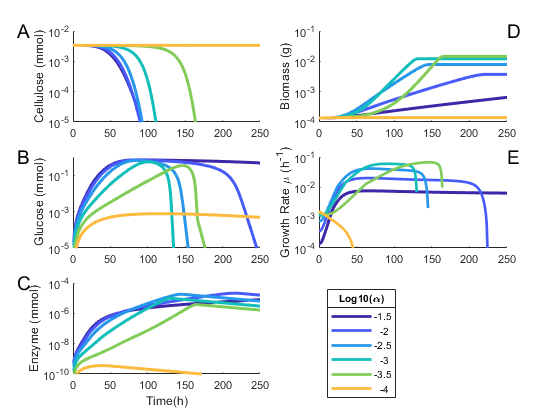

%alphas = pow2([-9 -11 -13]);

%kill a dumb rounding bug
d.log10alpha = round(log10(d.alpha),5);

alphas = [-1.5 -2 -2.5 -3 -3.5 -4];
d = d(ismember(d.log10alpha,alphas),:);
d = d(d.celscale == 1,:);
% d.log2alpha = log2(d.alpha);
% d.log10alpha = log10(d.alpha);
d = sortrows(d,'alpha','descend');
varIE = d.variableInitEnzyme(1);
colors = parula(length(alphas)+1);
colors = colors(1:end-1,:);
%colors = parula(length(alphas)+3);
%colors = colors(2:end,:);
%colors = lines(length(alphas));

xmax = 250;
yscale = 'log';
ymins = [1e-5 1e-4 1e-5 1e-7 1e-8]; %constantInitEnzyme
%yscale = 'linear';

f = figure();
hold on;
t = d.t{1};

subplot(3,2,1);
hold on
for i = 1:length(alphas)
    plot(t,d.cellulose_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Cellulose');
ylabel('Cellulose (mmol)');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    else
     ylim([1e-5 1e-2]);
     yticks([1e-5 1e-4 1e-3 1e-2]);
    end
end

text(-.3,1,'A','FontSize',fontsize,'Units',"normalized");

subplot(3,2,3);
hold on;
for i = 1:length(alphas)
    plot(t,d.glc_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Glucose');
ylabel('Glucose (mmol)');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-2 1]);
     %yticks([1e-4 1e-2 1e0]);
    else
     ylim([1e-5 1]);
     %yticks([1e-4 1e-2 1e0]);
     yticks([1e-5 1e-3 1e-1]);
    end
end

text(-.3,1,'B','FontSize',fontsize,'Units',"normalized");

subplot(3,2,2);
hold on;
for i = 1:length(alphas)
    plot(t,d.biomass{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Biomass');
ylabel('Biomass (g)');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    else
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    end
end
text(1,1,'D','FontSize',fontsize,'Units',"normalized");

subplot(3,2,5);
hold on;

for i = 1:length(alphas)
    plot(t,d.enzyme_amt{i},'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Enzyme');
ylabel('Enzyme (mmol)');

xlim([0 xmax]);
xlabel('Time(h)');
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-9 1e-4]);
     yticks([1e-8 1e-6 1e-4]);
    else
     %ylim([1e-8 1e-3]);
     %yticks([1e-7 1e-5 1e-3]);
     ylim([1e-10 1e-4]);
     yticks([1e-10 1e-8 1e-6 1e-4]);
    end
end
text(-.3,1,'C','FontSize',fontsize,'Units',"normalized");

subplot(3,2,4);
hold on;
for i = 1:length(alphas)
    bio = d.biomass{i};
    biodelta = bio(2:end) - bio(1:end-1);
    mu = biodelta ./ bio(1:end-1);
    plot(t(1:end-1),mu,'linewidth',2,'color',colors(i,:));
%    plot(t(1:end-1),biodelta,'linewidth',2,'color',colors(i,:));
end
hold off;
%title('Growth Rate');
ylabel('Growth Rate \mu (h^-^1)');
xlim([0 xmax]);
set(gca,'yscale',yscale);
if strcmp(yscale,'log')
    if varIE
     ylim([1e-7 1e-2]);
     yticks([1e-6 1e-4 1e-2]);
    else
     %ylim([1e-7 1e-2]);
     %yticks([1e-6 1e-4 1e-2]);
     ylim([1e-4 1e-1]);
     yticks([1e-4 1e-3 1e-2 1e-1]);
    end
end
text(1,1,'E','FontSize',fontsize,'Units',"normalized");

subplot(3,2,6);
hold on;
for i = 1:length(alphas)
    plot(NaN,NaN,'LineWidth',2,'color',colors(i,:));
end
hold off;
leg = legend(num2str(alphas'),'location','west');
set(gca,'Visible','off');
title(leg,'Log10(\alpha)');
hold off;

%save the figure
if overwritefiles
    savefig(f,[figpath,'fig3.fig'],'compact');
    saveas(f,[figpath,'fig3.png']);
    saveas(f,[figpath,'fig3.eps']);%for LaTeX
end